# DC servos and position control 

This livescript is a brief manual in support of the app ***dcservo_and_position_control.mlapp***.   This is a simple interface to investigate the  learning outcomes: how do DC servos behave and how do I ensure they deliver the correct position?  This scenario is represented by a small 'passenger on a seat'; the DC servo is used to drive the seat position. Clearly this could represent a printer and/or many other real scenarios where motors are used to resposition  engineering components.

More specifically the app allows the user to experiment with the following important aspects for control design.

- What is the impact of compensator gains (here we use PI) on closed-loop performance?

- What is the impact of changes in the engineering scenario such as gear ratios and load mass on closed-loop performance?

- What is the impact of the DC servo specification in behaviour? Here we consider  the torque available for a given voltage as a core characterisation.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context of DC servo with a load

- Defining the model in MATLAB and open-loop behaviour

- Feedback design.

- Impact of disturbances

- Image and components and animation.

## 1. Engineering context of DC servo with a load

This note will take a relatively simple DC servo model. The electrical part of the servo has an equation given as:

$u_a =\textrm{iR}+L\frac{\textrm{di}}{\textrm{dt}}+e=\textrm{iR}+L\frac{\textrm{di}}{\textrm{dt}}+kw_m ,$ where* e* is the back emf, *R*  is the internal resistance, $u_a$ the supplied voltage, *k* a core motor property and $w_m$ is the motor frequency of rotation. It is noted that the torque provided also depends upon *k*, so:

$\tau =\textrm{ki}$, and thus this parameter is a core variable within the app and within the specification of a DC servo.

The mechanical part of the servo is governed by the equations:

$\tau =K\left(\theta_m -\theta_l \right);\;\;\tau =Bw_l +J\frac{dw_l }{\textrm{dt}}$;   with no gearing, $w_l$ the angular velocity of the load and *J* the inertia of the load and *K* the shaft stiffness.

Adding some gearing, as shown below, adds the following details to the modelling.

$\tau =J_m \frac{R_2 }{R_1 }\frac{dw_l }{\textrm{dt}}+\left\lbrack \frac{J_L }{R_2 }\frac{dw_l }{\textrm{dt}}+\frac{B}{R_2 }w_l \right\rbrack R_1$;     Let $R_2 =nR_1$ and load velocity $v=rw_l$.

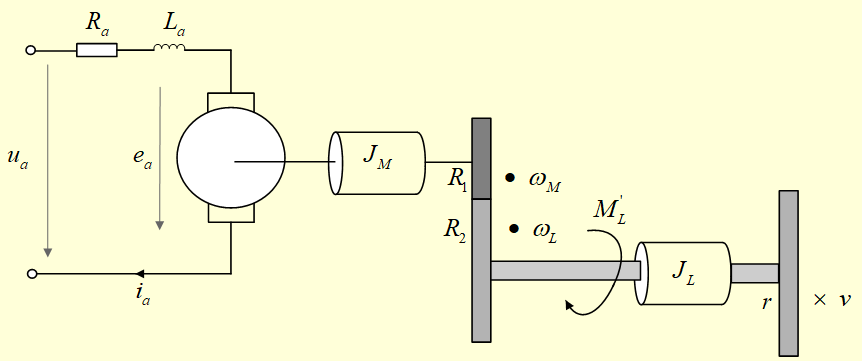

After some re-arrangement, and assuming the shaft is stiff so that $\theta_m =\theta_l$, the overall model reduces to:


$$u_a =\frac{L}{k}\left(nJ_m +\frac{J_l }{n}\right)\frac{d^2 w_l }{dt^2 }+\left(\frac{R}{k}\left\lbrack nJ_m +\frac{J_l }{n}\right\rbrack +\frac{\textrm{LB}}{\textrm{kn}}\right)\frac{dw_l }{\textrm{dt}}+\left(\frac{\textrm{BR}}{\textrm{nk}}+\textrm{kn}\right)w_l$$


This is a 2nd order ODE. For simplicity the impact on the modelling of the linear motion is taken as implicit or included within the rotational inertia.

Specifically here we will investigate the impact of the two parameters:* k* and $J_l$ and take the other parameters as fixed. As the focus is on understanding core concepts and impacts, the numbers used will be simplified rather than representing a real servo and load (although these are  strongly related to a piece of hardware in the author's department).

$k=0\ldotp 4\;\frac{\textrm{Vs}}{\textrm{rad}};J_m =0\ldotp 002\;\textrm{kg}m^2 ,J_l =0\ldotp 02\;\textrm{kg}m^2 ,n=10,R=4\Omega ,L=0\ldotp 06H,r=0\ldotp 05m,B=0\ldotp 001$.

### 1.1 Expected impact on open-loop behaviour of parameter changes

The user is invited to use engineering insight, understanding of the modelling above and other means to suggest how the behaviour might change with different parameter choices. Some illustrations are given in section 2 below. The illustrations here are on load speed.

### 1.2 Feedback Design

Some illustrations of this are given in section 3 below. There are two possible requirements, that is, either speed or position control of the load.

- The system includes an integrator when the output is displacement and thus proportional compensation may be sufficient.

- When the output is velocity, a PI compensator could be investigated.

## 2. Defining the model in MATLAB and open-loop behaviour

We can use MATLAB to investigate different effects by computing responses for a range of values for the different servo/load parameters.

### 2.1 Impact of changing the load inertia

If the load inertia is increased one would expect slower acceleration and thus slower transient velocities. Within a closed-loop where the steady-state is fixed, this could lead to slower time constants.

% Define the model with output velocity
disp('Impact of changing load inertia')

Impact of changing load inertia


B=0.008; Jm = 6*10^(-7);n=10;k=0.015;
L=7*10^(-5);R=2;Jl=0.02;r = 0.05;
Jl = [0.01, 0.02, 0.04 0.06]

Jl =     0.0100    0.0200    0.0400    0.0600


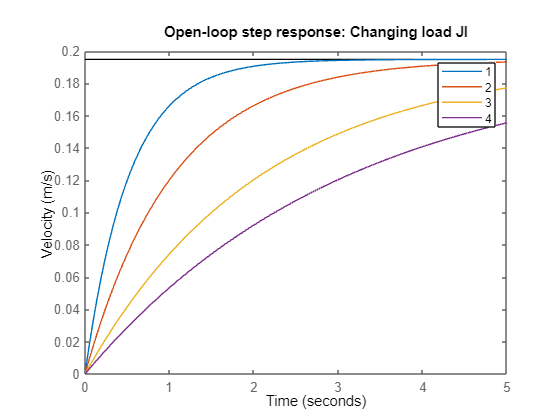

G=cell(1);
figure
for kk=1:4;
    a1(kk) = (L/k)*(n*Jm+(Jl(kk)/n));
    a2(kk) = (R/k)*(n*Jm+(Jl(kk)/n))+(L*B/(k*n));
    a3(kk) = (B*R/(n*k))+ (k*n);
    G{kk} = tf(r,[a1(kk) a2(kk) a3(kk)]);
    step(G{kk},5); hold on
end
legend('1','2', '3','4')

title('Open-loop step response: Changing load Jl')
ylabel('Velocity (m/s)')

### 2.2 Impact of changing the servo gain parameter k 

The back emf increases with the variable *k* which implicitly means that the current and torque will reduce faster, perhaps meaning a faster time constant. The transient torque $\tau =\textrm{ki}$ will be larger with larger *k*, resulting in faster initial acceleration. However, for small *k* the back emf is  less at higher velocities, hence high steady-state velocities will become feasible.

% Define the model with output velocity
disp('Impact of changing load torque constant')
B=0.008; Jm = 6*10^(-7);n=10;k=0.015;L=7*10^(-5);R=2;Jl=0.02;r = 0.05;
k = [0.2, 0.4, 0.6 0.8]/10

k =     0.0200    0.0400    0.0600    0.0800


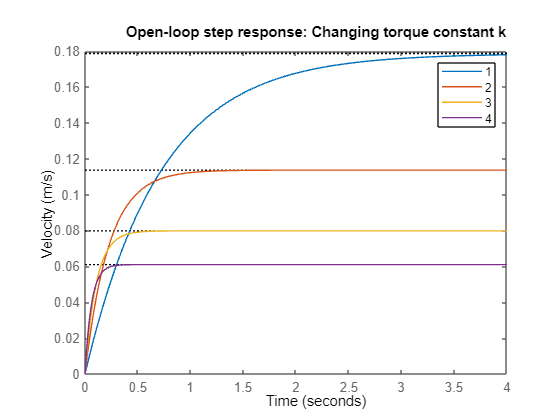

figure
for kk=1:4;
    a1(kk) = (L/k(kk))*(n*Jm+(Jl/n));
    a2(kk) = (R/k(kk))*(n*Jm+(Jl/n))+(L*B/(k(kk)*n));
    a3(kk) = (B*R/(n*k(kk)))+ (k(kk)*n);
    G{kk} = tf(r,[a1(kk) a2(kk) a3(kk)]);
    step(G{kk},4); hold on
end
legend('1','2', '3','4')

title('Open-loop step response: Changing torque constant k')
ylabel('Velocity (m/s)')

### 2.3 Impact of changing the changing the gear ratio

Increasing the gear ratio enables more torque to be delivered to the load so faster initial acceleration, but conversely a larger motor velocity  (larger back emf) is needed to deliver the desired load movement so the net impact is slower behaviour overall and lower steady-state speeds. High gear ratios are usually needed for high load, but low speeds.

% Define the model with output velocity
disp('Impact of changing gear ratio')

Impact of changing gear ratio


B=0.008; Jm = 6*10^(-7);Jl=0.02;k=0.015;L=7*10^(-5);R=2; r = 0.05;
n=[5,8 10, 20]

n =      5     8    10    20


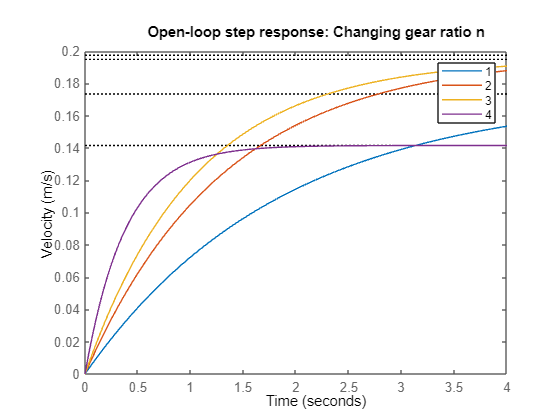

figure
for kk=1:4;
    a1(kk) = (L/k)*(n(kk)*Jm+(Jl/n(kk)));
    a2(kk) = (R/k)*(n(kk)*Jm+(Jl/n(kk)))+(L*B/(k*n(kk)));
    a3(kk) = (B*R/(n(kk)*k))+ (k*n(kk));
    G{kk} = tf(r,[a1(kk) a2(kk) a3(kk)]);
    step(G{kk},4); hold on
end
legend('1','2', '3','4')

title('Open-loop step response: Changing gear ratio n')
ylabel('Velocity (m/s)')

## 3. Notional feedback design

Two possible objectives are to control velocity or position. This app uses simple PI compensators for M(s).

- The app uses just proportional for position control, because the model for position already includes an integrator. If position control is selected the integral us automatically set to zero.

- The app uses PI for velocity control.

Indicative code is given below.

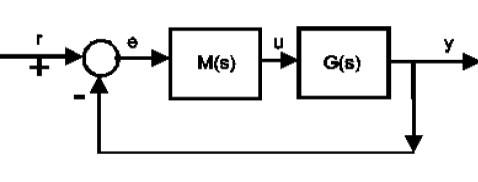

disp(' ')

disp('SECTION 3 BELOW: feedback control')

SECTION 3 BELOW


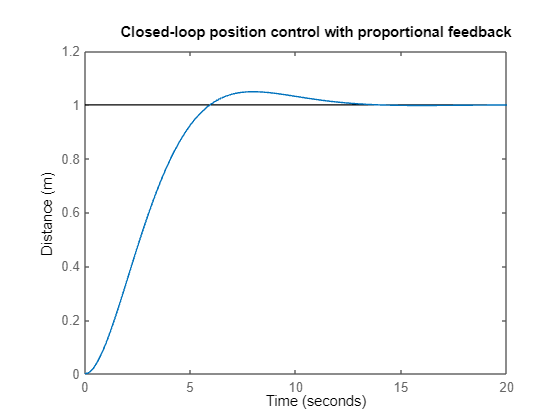

B=0.008; Jm = 6*10^(-7);Jl=0.02;k=0.015;L=7*10^(-5);R=2; n=8; r = 0.05;
a1= (L/k)*(n*Jm+(Jl/n));
a2 = (R/k)*(n*Jm+(Jl/n))+(L*B/(k*n));
a3 = (B*R/(n*k))+ (k*n);
Gm = tf(r,[a1 a2 a3 0]);
figure
Gc = feedback(2*Gm,1);
step(Gc,20)
title('Closed-loop position control with proportional feedback')
ylabel('Distance (m)')

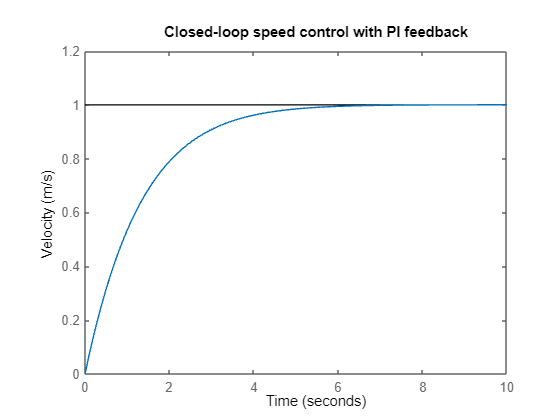


Gv = tf(r,[a1 a2 a3]);
M = tf([5,4],[1 0]); % PI compensator
figure
Gc = feedback(M*Gv,1);
step(Gc,10)
title('Closed-loop speed control with PI feedback')
ylabel('Velocity (m/s)')

It is not the purpose of this resource to examine the compensator design in detail, so this investigation is left to the user.

## 4. Impact of disturbances

Fritction is implicit within the system already through the parameter *B*, but for various reasons there could be temporary increases in rolling or motor friction. It will  be interesting to see how well the system manages to maintain position or velocity when subject to such disturbances. For clarity of impact, the disturbances are introduced mid-simulation and for part of the simulation time before being switched off again; hence the impact of the disturbance on behaviour becomes evident.  The figure here shows a typical comparison between open-loop speed with no transient friction and speed when, between times 5-8 seconds, extra friction is introduced.

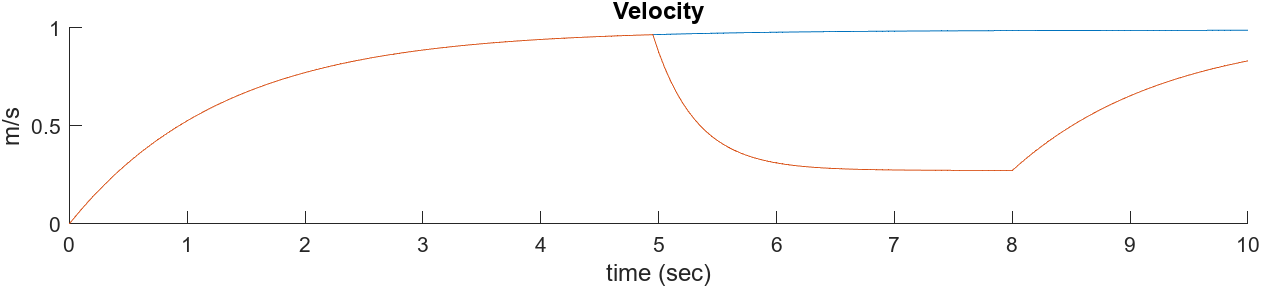

## 5. Image and components and animation

The image shows a person on a seat on a track. A circular track is used for speed control and a straight line track for position. The seat is driven by a DC servo as described in section 1 above. The person and seat will move along the track to represent speed/position.

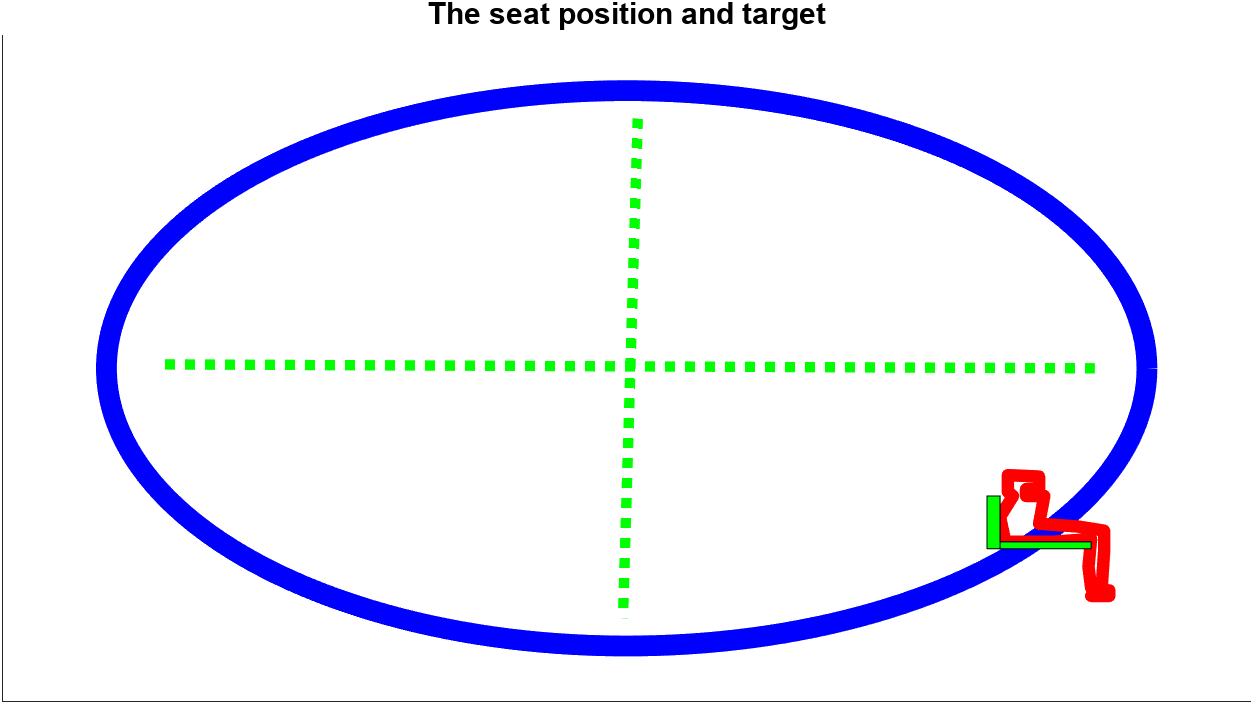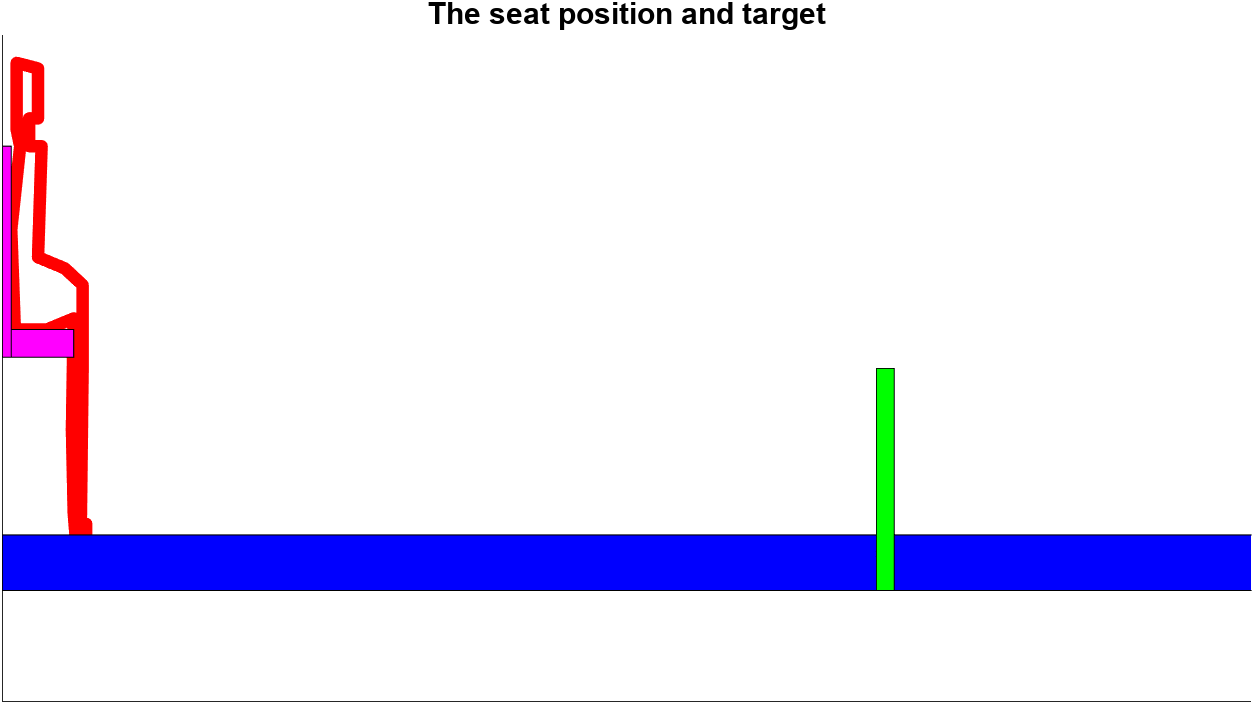

The user can change only a few parameters using sliders in order to investigate the impact on behaviour. 

- The load inertia (system parameter).

- The troque constant k (system parameter).

- The gear ratio n (system parameter).

- The friction parameter B (system parameter).

- The proportional gain Kp (control parameter).

- The integral gain Ki  (control parameter).

The app keeps track of previous choices so that overlaying of responses can be used to investigate the impact of parameter changes.  Use the refresh button to begin again. The simulation assumes a zero initial condition.

The animation can be switched off for quicker run times. Some typical pen-loop behaviours are shown in the image below.